# Code to evualute $P_{r_\mathrm{in}}(T_\mathrm{out}<T_\mathrm{upd})$

### Evaluating $$P_{J\mathrm{out}}$$


$$P_{J\mathrm{out}}(j)=\left(\frac{A_\mathrm{in}}{A}\right)^j\left(1-\frac{A_\mathrm{in}}{A}\right)$$


J=7;%total of convolutions and jumps
j =1:J;

r_select=1;%radius selection for plotting

r_A=r_inner/r_outer;%ratio of areas
P_j_out=zeros(length(r_A),J);
init_point=0;
end_point=length(j);

for r=1:length(r_A)
    P_j_out(r,:)=r_A(r).^(j-1)*(1-r_A(r));    
end

% figure;
% color = {'#0072BD','#D95319','#EDB120','#7E2F8E','#77AC30','#4DBEEE','#A2142F'}; %list of colors from https://www.mathworks.com/help/matlab/creating_plots/specify-plot-colors.html
% line_width=linspace(1,3,length(color));%specify the width for each line in the plot
% marker={'-','-+','-d','-.','-x','-o','-s','-*','-|','-^'};% marker symbols are given at https://www.mathworks.com/help/matlab/creating_plots/create-line-plot-with-markers.html
% marker_size=1:length(color);%specify the width for each marker in the plot
% marker_indices=1:length(color);%specify the length between markers
% step=round(length(r_A)/10);
% total_curves=3;
% m=1;
% for r=1:step:total_curves
%     plot(j,P_j_out(r,:),marker{m},'Color',color{m},'LineWidth',line_width(length(color)-m+1),...
%         'MarkerEdgeColor',color{m},'MarkerFaceColor',color{m});hold on;
%     m=m+1;
% end
% 
% grid on;
% 
% r=1:step:total_curves;
% legend_text=cell(1,length(r));
% for m=1:floor(length(r))
%   legend_text{m}=strcat('$\frac{A_c}{A}=',num2str(r_A(r(m))*100,2),'$\%');
% end
% 
% legend({legend_text{:}},...
%     'Location','northeast','NumColumns',2,'Interpreter',"latex",'FontSize',fontsize);% more properties on the legend at https://www.mathworks.com/help/matlab/ref/legend.html
% grid on;
% hold off %to close the canvas
% 
% xlabel('Jumps $(j)$','Interpreter','latex');
% ylabel('$P_{J\mathrm{out}}(j)$','Interpreter','latex');
% set(gca,'FontSize',fontsize);
% axis([1 j(end) 0 1.1*max(max(P_j_out))]);

### Evaluating $f_{\tau_j;r_\mathrm{in}}}$

$f_{\tau_{pj};r_{in}}=\int_{v_\mathrm{min}}^{{v_\mathrm{max}}}{vf_{\tau_j;r_{in}}(v\tau)f_{V}(v)\mathrm{d}v}$, [1, Eq. (32)]

where

$f_{V}(v)=\frac{1}{v_\mathrm{max}-v_\mathrm{min}}$ is the user's velocity PDF [1, Example 3.5.1]

$f_{\tau_j;r_\mathrm{in}}=vf_{L}(v\!\tau_j;r_\mathrm{in})$ is the PDF for the time duration per jump [1, Eq. (28)]

$f_{L}(l_j;r_{in})=\frac{8}{\pi r_\mathrm{in}}\frac{l_j}{2r_\mathrm{in}}\left(\arccos\frac{l_j}{2r_\mathrm{in}}-\frac{l_j}{2r_\mathrm{in}}\sqrt{1-\left(\frac{l_j}{2r_\mathrm{in}}\right)^2}\right)$ is the PDF for the jump's length [1, Eq. (23)]

%pre-allocating space
f_tau_j_v=cell(length(f_V),length(r_inner));%evaluates the PDF in the velocity-time grid

for v_i=1:length(f_V)
    v=v_vector(v_i);
    for r=1:length(r_inner)
        tau_j=0:delta_tau_j:2*r_inner(r)/v;
        f_tau_j_v{v_i,r}=horzcat(v*8/(pi*r_inner(r))*v*tau_j/(2*r_inner(r)).*(acos(v*tau_j/(2*r_inner(r)))-(v*tau_j/(2*r_inner(r))).*sqrt(1-(v*tau_j/(2*r_inner(r))).^2)),...
            zeros(1,floor(2*(r_inner(end)/v_vector(1)/delta_tau_j)-length(tau_j))+1));
    end
end

%evaluating the integral
f_tau_j=cell(1,length(r_inner));%evaluates the PDF in the velocity-time grid

for r=1:length(r_inner)
    f_tau_vector_temp=zeros(1,length(f_tau_j_v{1,1}));
    for v_i=1:length(f_V)
        f_tau_vector_temp=f_tau_vector_temp+f_tau_j_v{v_i,r}.*f_V(v_i);
    end
    f_tau_j{r}=f_tau_vector_temp*(v_min_max(2)-v_min_max(1))/total_v;
end

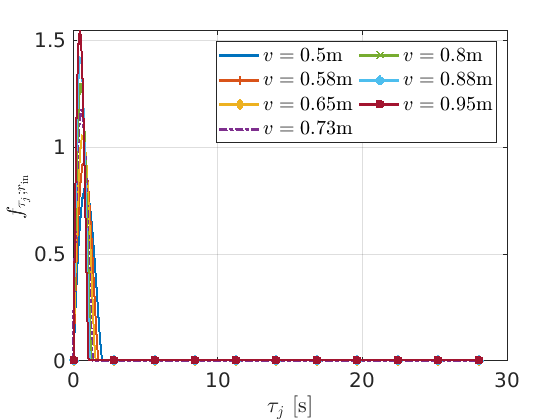

figure;
total_curves=7;
step=ceil(length(f_V)/total_curves);
r_select=1;
v=1:step:length(f_V);
for j=1:length(v)
    tau_j=(0:1:(length(f_tau_j_v{v(j),r_select})-1))*delta_tau_j;
    plot(tau_j,f_tau_j_v{v(j),r_select},marker{j},'Color',color{j},'LineWidth',2,...
        'MarkerEdgeColor',color{j},'MarkerFaceColor',color{j},'MarkerIndices',1:round(length(tau_j)/10):length(tau_j)); hold on;
end

grid on;
hold off %to close the canvas


legend_text=cell(1,length(v));
for m=1:length(v)
  legend_text{m}=strcat('$v=',num2str(v_vector(v(m)),2),'$m');
end

legend({legend_text{:}},...
    'Location','northeast','NumColumns',2,'Interpreter',"latex",'FontSize',fontsize);% more properties on the legend at https://www.mathworks.com/help/matlab/ref/legend.html
grid on;
hold off %to close the canvas

xlabel('$\tau_j$ [s]','Interpreter','latex');
ylabel('$f_{\tau_j;r_\mathrm{in}}$','Interpreter','latex');
set(gca,'FontSize',fontsize);

% axis([0 tau_j(end) 0 1.1*max(f_tau_j{1})]);

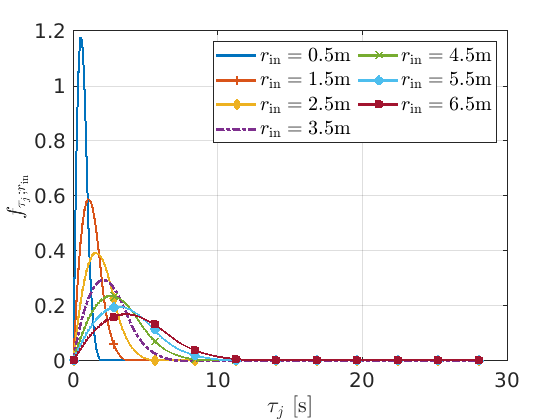

figure;
total_curves=7;
step=ceil(length(r_inner)/total_curves);
r_select=1;
r=1:step:length(r_inner);
for j=1:length(r)
    tau_j=(0:1:(length(f_tau_j{j})-1))*delta_tau_j;
    plot(tau_j,f_tau_j{j},marker{j},'Color',color{j},'LineWidth',2,...
        'MarkerEdgeColor',color{j},'MarkerFaceColor',color{j},'MarkerIndices',1:round(length(tau_j)/10):length(tau_j)); hold on;
end

grid on;
hold off %to close the canvas


legend_text=cell(1,length(r));
for m=1:length(r)
  legend_text{m}=strcat('$r_\mathrm{in}=',num2str(r_inner(r(m)),2),'$m');
end

legend({legend_text{:}},...
    'Location','northeast','NumColumns',2,'Interpreter',"latex",'FontSize',fontsize);% more properties on the legend at https://www.mathworks.com/help/matlab/ref/legend.html
grid on;
hold off %to close the canvas

xlabel('$\tau_j$ [s]','Interpreter','latex');
ylabel('$f_{\tau_j;r_\mathrm{in}}$','Interpreter','latex');
set(gca,'FontSize',fontsize);

% axis([0 tau_j(end) 0 1.1*max(f_tau_j{1})]);

### Evaluating $f_{T_\mathrm{out}}(t_\mathrm{out}|j)$ for a given inner circle radius $r_{\textrm{in}}$


$$f_{T_\mathrm{out}}(t_\mathrm{out}|j)=
    \underbrace{f_{\tau_j;r_\mathrm{in}}\ast \cdots \ast f_{\tau_j;r_\mathrm{in}}}_{j}\big|_{\tau_j=t_\mathrm{out}}$$


%evaluating the N-fold convolution
f_tau=cell(length(r_inner),J);

for r=1:length(r_inner)
    f_tau{r,1}=f_tau_j{r};
    for j=2:J
        f_tau{r,j}=conv(f_tau{r,j-1},f_tau_j{r})*delta_tau_j;
    end
end


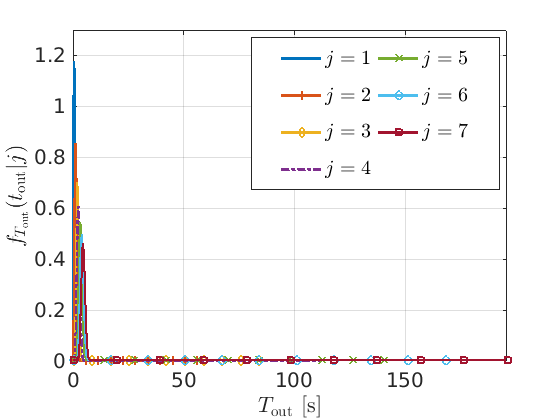

figure;
total_curves=7;
step=ceil(J/total_curves);
r=1:step:J;
r_select=1;
for j=1:step:total_curves
    %tau=0:delta_tau_j:j*2*r_inner(r_select)/v;
    tau=(0:1:(length(f_tau{r_select,j})-1))*delta_tau_j;
    plot(tau,f_tau{r_select,j},marker{j},'Color',color{j},'LineWidth',2,'MarkerIndices',1:round(length(tau)/10):length(tau)); hold on;
end
grid on;

legend_text=cell(1,J);
for m=1:J
  legend_text{m}=strcat('$j=',num2str(r(m),2),'$');
end

legend({legend_text{:}},...
    'Location','northeast','NumColumns',2,'Interpreter',"latex",'FontSize',fontsize);% more properties on the legend at https://www.mathworks.com/help/matlab/ref/legend.html
grid on;
hold off %to close the canvas

legend("Position", [0.44859,0.5482,0.44286,0.3619]);
xlabel('$T_\mathrm{out}$ [s]','Interpreter','latex');
ylabel('$f_{T_\mathrm{out}}(t_\mathrm{out}|j)$','Interpreter','latex');
set(gca,'FontSize',fontsize);
axis([0 tau(end) 0 1.1*max(f_tau{r_select,1})]);

figure;
total_curves=7;
step=ceil(length(r_inner)/total_curves);
r=1:step:length(r_inner);
j=1;
for r_select=1:step:total_curves
    %tau=0:delta_tau_j:j*2*r_inner(r_select)/v;
    tau=(0:1:(length(f_tau{r_select,j})-1))*delta_tau_j;
    plot(tau,f_tau{r_select,j},marker{j},'Color',color{r_select},'LineWidth',2,'MarkerIndices',1:round(length(tau)/10):length(tau)); hold on;
end
grid on;

legend_text=cell(1,length(r));
for m=1:floor(length(r))
  legend_text{m}=strcat('$r=',num2str(r_inner(r(m)),2),'$');
end

legend({legend_text{:}},...
    'Location','northeast','NumColumns',2,'Interpreter',"latex",'FontSize',fontsize);% more properties on the legend at https://www.mathworks.com/help/matlab/ref/legend.html

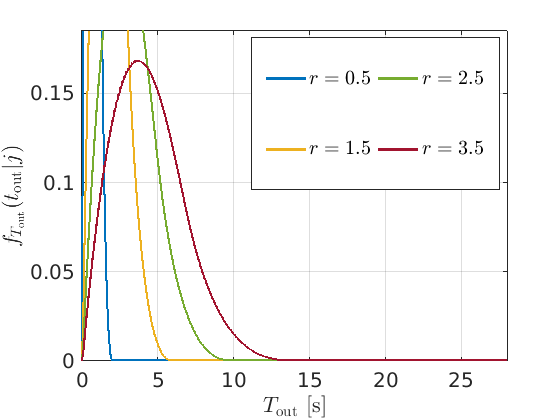

grid on;
hold off %to close the canvas

legend("Position", [0.44859,0.5482,0.44286,0.3619]);
xlabel('$T_\mathrm{out}$ [s]','Interpreter','latex');
ylabel('$f_{T_\mathrm{out}}(t_\mathrm{out}|j)$','Interpreter','latex');
set(gca,'FontSize',fontsize);
axis([0 tau(end) 0 1.1*max(f_tau{r_select,1})]);

### Evaluating $P(T_\mathrm{out}|j)$


$$P(T_\mathrm{out}|j)=\int_0^{T_\mathrm{out}}{f_{T_\mathrm{out}}(t_\mathrm{out}|j)\mathrm{d}t_\mathrm{out}}$$


P_T_out_j=cell(length(r_inner),J);

for r=1:length(r_inner)
    for j=1:J
        P_T_out_j{r,j}=horzcat(cumtrapz(f_tau{r,j})*delta_tau_j,ones(1,length(f_tau{r,end})-length(f_tau{r,j})));
    end
end



% figure;
% total_curves=7;
% step=ceil(length(r_inner)/total_curves);
% r=1:step:length(r_inner);
% 
% for j=1:7
% %     tau=0:delta_tau_j:J*2*r_inner(r_select)/v;
%     tau=(0:1:(length(P_T_out_j{r_select,j})-1))*delta_tau_j;
%     plot(tau,P_T_out_j{r_select,j},marker{j},'Color',color{j},'LineWidth',2,...
%         'MarkerEdgeColor',color{j},'MarkerFaceColor',color{j},'MarkerIndices',1:round(length(tau)/10):length(tau)); hold on;
% end
% grid on;
% 
% 
% legend_text=cell(1,length(r));
% for m=1:floor(length(r))
%   legend_text{m}=strcat('$j=',num2str(r(m),2),'$');
% end
% 
% legend({legend_text{:}},...
%     'Location','northeast','NumColumns',2,'Interpreter',"latex",'FontSize',fontsize);% more properties on the legend at https://www.mathworks.com/help/matlab/ref/legend.html
% grid on;
% hold off %to close the canvas
% 
% legend("Position", [0.44859,0.5482,0.44286,0.3619]);
% xlabel('$T_\mathrm{out}$ [s]','Interpreter','latex');
% ylabel('$P(T_\mathrm{out}|j)$','Interpreter','latex');
% set(gca,'FontSize',fontsize);
% axis([0 tau(end) 0 1.1]);

### Evaluating $P_\mathrm{fh\_out}(T_\mathrm{out}<T_\mathrm{upd})$ and $P_{r_\mathrm{in}}(T_\mathrm{out}<T_\mathrm{upd})$

where


$$P_\mathrm{fh\_out}(T_\mathrm{out}<T_\mathrm{upd})=\sum_{j=1}^\infty {P(T_\mathrm{out}|j)P_{J\mathrm{out}}(j)}$$


and


$$P_{r_\mathrm{in}}(T_\mathrm{out}<T_\mathrm{upd})=1-P_\mathrm{fh\_out}(T_\mathrm{out}<T_\mathrm{upd})$$



P_fh_out=zeros(length(r_inner),length(P_T_out_j{end}));


for r=1:length(r_inner)
    for j=1:J
        P_fh_out(r,:)=P_fh_out(r,:)+horzcat(P_T_out_j{r,j}*P_j_out(r,j),zeros(1,length(P_T_out_j{end,end})-length(P_T_out_j{r,j})));        
    end
end

P_r_in=1-P_fh_out;

% figure;
% total_curves=7;
% step=ceil(length(r_inner)/total_curves);
% r=1:step:length(r_inner);
% tau=0:delta_tau_j:J*2*r_inner(end)/v;
% for j=1:1:length(r)
%     plot(tau,P_fh_out(r(j),:),marker{j},'LineWidth',2,'Color',color{j},'LineWidth',2,'MarkerIndices',1:round(length(tau)/10):length(tau)); hold on;
% end
% 
% legend_text=cell(1,length(r));
% for m=1:floor(length(r))
%   legend_text{m}=strcat('$r_\mathrm{in}=',num2str(r_inner(r(m)),2),'$m');
% end
% 
% legend({legend_text{:}},...
%     'Location','northeast','NumColumns',2,'Interpreter',"latex",'FontSize',fontsize);% more properties on the legend at https://www.mathworks.com/help/matlab/ref/legend.html
% grid on;
% hold off %to close the canvas
% 
% grid on;
% xlabel('$T_\mathrm{upd}$ [s]','Interpreter','latex');
% ylabel('$P_{\mathrm{fh\_in}}(T_\mathrm{out}<T_{\mathrm{upd}})$','Interpreter','latex');
% set(gca,'FontSize',fontsize);
% axis([0 tau(length(P_T_out_j{1,1})-1) 0 1.1*max(max(P_fh_out))]);
% 
% legend("Position", [0.48163,0.22027,0.40624,0.18333])

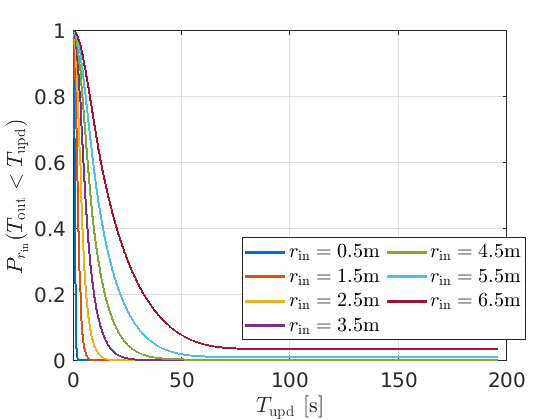


figure;
total_curves=7;
step=ceil(length(r_inner)/total_curves);
r=1:step:length(r_inner);
[~,length_tau]=size(P_r_in);
for j=1:1:length(r)
    plot((0:length_tau-1)*delta_tau_j,P_r_in(r(j),1:length_tau),'LineWidth',2,'Color',color{j},'LineWidth',2,'MarkerIndices',1:round(length(tau)/10):length(tau)); hold on;
end

legend_text=cell(1,length(r));
for m=1:floor(length(r))
  legend_text{m}=strcat('$r_\mathrm{in}=',num2str(r_inner(r(m)),2),'$m');
end

legend({legend_text{:}},...
    'Location','northeast','NumColumns',2,'Interpreter',"latex",'FontSize',fontsize);% more properties on the legend at https://www.mathworks.com/help/matlab/ref/legend.html
grid on;
hold off %to close the canvas

legend("Position", [0.48163,0.22027,0.40624,0.18333]);

grid on;
xlabel('$T_\mathrm{upd}$ [s]','Interpreter','latex');
ylabel('$P_{r_\mathrm{in}}(T_\mathrm{out}<T_{\mathrm{upd}})$','Interpreter','latex');
set(gca,'FontSize',fontsize);

%axis([0 tau(length(P_T_out_j{1,1})-1) 0 1.1*max(max(P_fh_out))]);

### Evaluating the average PAoI regarding the loc updates

% T_loc=10^(-3);%localization time interval
% T_d=10^(-6);%transmission delay
% T_coh=10^(-3);%coherence time
% T_IRS=10^(-3);%IRS-updating time
% 
% figure;
% T_upd=tau;
% for r=1:length(r_inner)
% %     delta_PAoI=T_d+1./(P_tau(r,:)).*(T_coh+T_coh./T_upd*(T_loc+T_IRS));
%     delta_PAoI=T_d+1./(P_fh_out(r,:)).*T_upd;
%     semilogy(T_upd,delta_PAoI,marker{r},'LineWidth',2,'Color',color{r},'LineWidth',2,...
%         'MarkerIndices',1:100:length(P_T_out_j{1,1})-1, ...
%         'MarkerEdgeColor',color{r},'MarkerFaceColor',color{r}); hold on;
% end
% 
% % 
% 
% grid on;
% 
% legend_text=cell(1,length(r_inner));
% for m=1:length(r_inner)
%   legend_text{m}=strcat('$r_c=',num2str(r_inner(m)),'$ m');
% end
% 
% legend({legend_text{:}},...
%     'Location','northeast','NumColumns',2,'Interpreter',"latex",'FontSize',fontsize);% more properties on the legend at https://www.mathworks.com/help/matlab/ref/legend.html
% 
% xlabel('$T_\mathrm{upd}$ [s]','Interpreter','latex');
% ylabel('$\Delta^{(p)}$','Interpreter','latex');
% set(gca,'FontSize',fontsize);
% axis([0 T_upd(length(P_T_out_j{1,1})-1) 0 2*10^(2)]);
% 
% legend("Position", [0.48272,0.16688,0.40624,0.18333]);
% 

### Evaluating the average PAoI regarding the info-data updates

% T_loc=10^(-3);%localization time interval
% T_d=10^(-6);%transmission delay
% T_coh=10^(-3);%coherence time
% T_IRS=10^(-3);%IRS-updating time
% 
% figure;
% T_upd=tau;
% for r=1:length(r_inner)
%     delta_PAoI=T_d+1./(P_fh_out(r,:)).*(T_coh+T_coh./T_upd*(T_loc+T_IRS));
% %     delta_PAoI=T_d+1./(P_tau(r,:)).*T_upd;
%     semilogy(T_upd,delta_PAoI,marker{r},'LineWidth',2,'Color',color{r},'LineWidth',2,...
%         'MarkerIndices',1:100:length(P_T_out_j{1,1})-1, ...
%         'MarkerEdgeColor',color{r},'MarkerFaceColor',color{r}); hold on;
% end
% 
% % 
% 
% grid on;
% 
% legend_text=cell(1,length(r_inner));
% for m=1:length(r_inner)
%   legend_text{m}=strcat('$r_c=',num2str(r_inner(m)),'$ m');
% end
% 
% legend({legend_text{:}},...
%     'Location','northeast','NumColumns',2,'Interpreter',"latex",'FontSize',fontsize);% more properties on the legend at https://www.mathworks.com/help/matlab/ref/legend.html
% 
% xlabel('$T_\mathrm{upd}$ [s]','Interpreter','latex');
% ylabel('$\Delta^{(p)}$','Interpreter','latex');
% set(gca,'FontSize',fontsize);
% axis([0 T_upd(length(P_T_out_j{1,1})-1) 10^(-2) 10^(2)]);
% 
% legend("Position", [0.40209,0.72965,0.48958,0.18333])

#### Interception of two circunferences in polar coordinates

% syms l l_r x r_c r_a a b phi
% 
% P_L=int(1/(r_c/r_a*(1-r_c/r_a))*(x+l-r_c),[r_c-l,r_c])
% 
% int(l*acos((l^2+l_r^2+a)/(2*l*a)),l)
% 
% p_l=diff(P_L,l)
% 
% p_l_r=(l_r*r_a^2)/(2*(r_a - r_c)) - (r_a^2*(l + 2*r_c))/(2*r_c*(r_a - r_c))
% 
% p_l=l_r*r_a^2
% 
% % fplot(p_l)
% 
% 

% syms l A n s
% 
% f(l)=-2/A^2*l+2/A;
% 
% 
% M_L=int(exp(s*l)*f,l,[0 A])^1
% A=10;
% 
% int(exp(-s*l)*M_L,s,[0 inf])

### References

[1] C. Bettstetter, H. Hartenstein, and X. Costa-Pérez, “Stochastic Properties of the Random Waypoint Mobility Model,” Wireless Networks, vol. 10, no. 5, pp. 555–567, Sep. 2004.